clear; close all; clc
addpath('dep')

%% load a file
dataLoc = '~/Downloads/v4-7a';
load([dataLoc '/zippy_grid_2afc_240710-134739_dense.mat'])

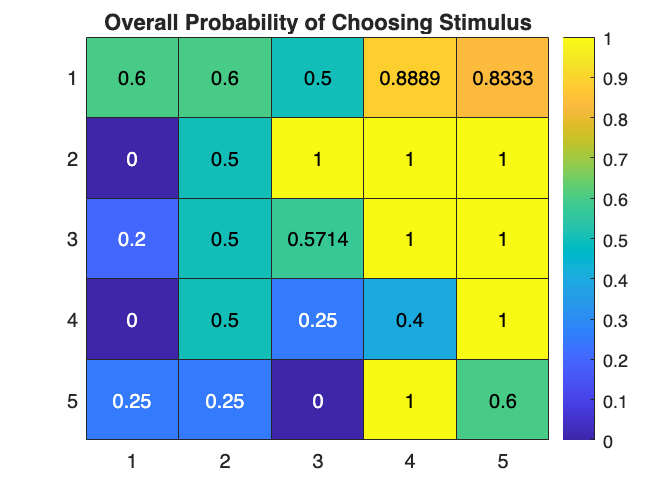

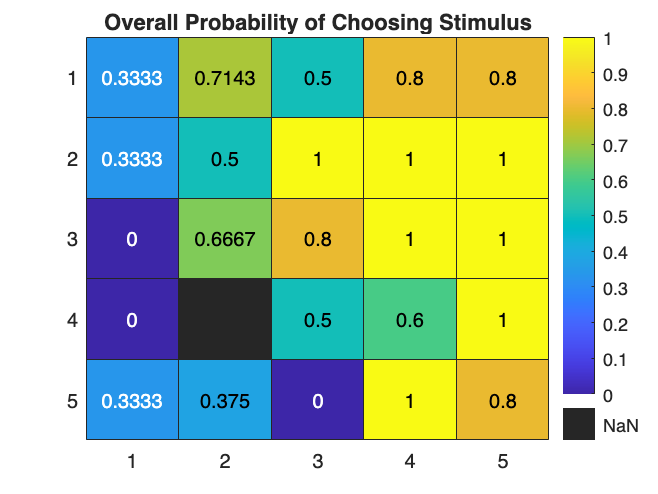

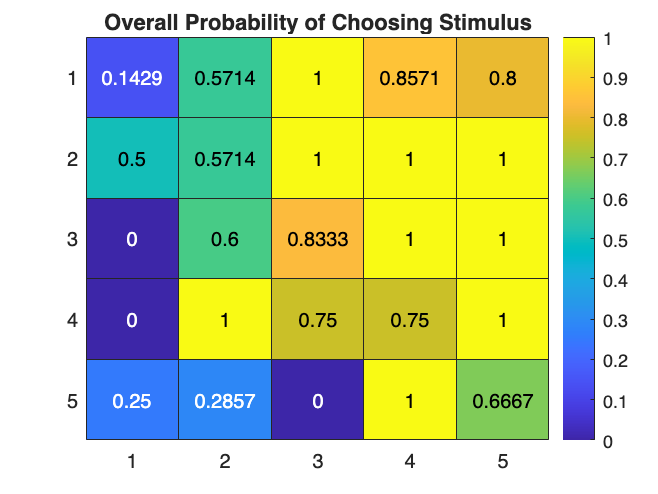

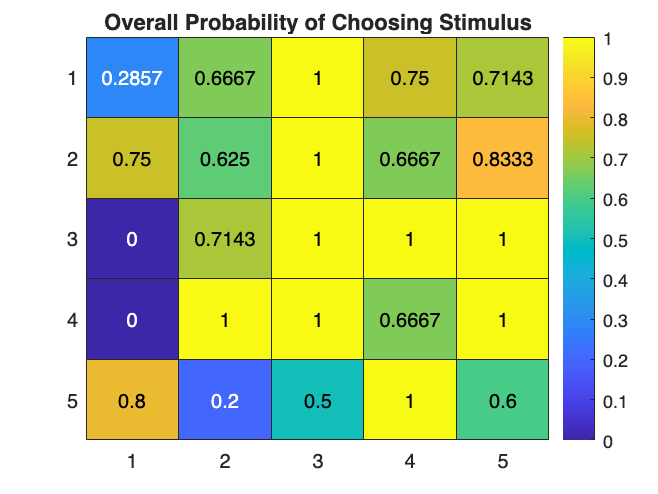

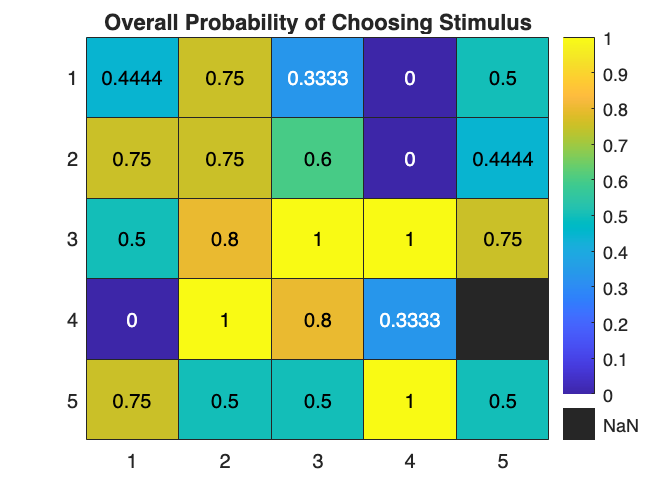

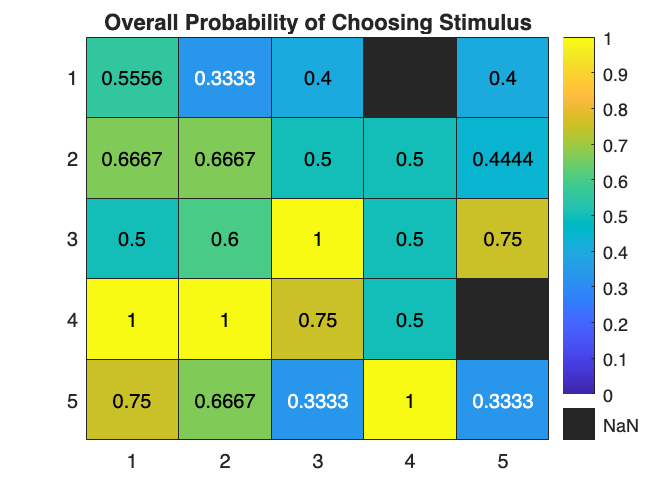

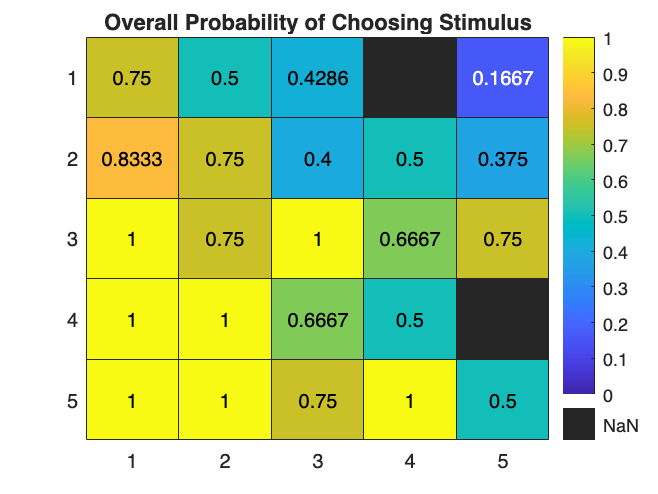

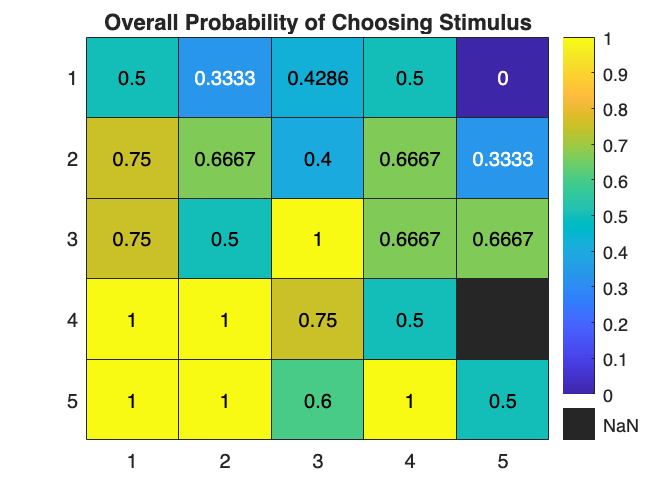

left_i = 1;
i = 1;
while left_i + 100 < length(params)
    window = params(left_i: left_i + 100);
    figure(i)
    plotSlidingHM(window)
    left_i = left_i + 20;
    i = i + 1;
end

function plotSlidingHM(params)
    gen_HM = NaN(5);
    for stim = 1:25
        overall_stim_choices = sum([params.stimRF_num] == stim & [params.selected] == 1); 
        overall_stims = sum([params.stimRF_num] == stim);
        gen_HM(stim) = overall_stim_choices/overall_stims;
    end
    gen_HM = gen_HM.';
    heatmap(gen_HM, 'ColorLimits', [0, 1], 'ColorMap', parula)
    title("Overall Probability of Choosing Stimulus")
end